# Landmark localization

Simulation of a robot moving in a 2d plane. Measurements are taken by beacons, which transmit the range back to the robot.

Date Started : 13 Dec. 2023 , 4: 30 PM

Author : Giorgio Ridolfi

## Sources

[https://stackoverflow.com/questions/39818915/matlab-how-to-get-the-specs-of-the-host-machine](https://stackoverflow.com/questions/39818915/matlab-how-to-get-the-specs-of-the-host-machine)

[https://undocumentedmatlab.com/](https://undocumentedmatlab.com/)

## System Info

close all
clc
display("OS : " + computer("arch") + ", " + feature('GetOS') )

    "OS : glnxa64, Linux 6.5.6-76060506-generic #202310061235~1697396945~22.04~9283e32 SMP PREEMPT_DYNAMIC Sun O x86_64"



display("Processor : " + feature('GetCPU') + ", " + feature('numCores') )

    "Processor : 11th Gen Intel(R) Core(TM) i7-11370H @ 3.30GHz, 4"



GPU = gpuDevice

GPU =   CUDADevice with properties:

                      Name: 'NVIDIA GeForce RTX 3050 Laptop GPU'
                     Index: 1
         ComputeCapability: '8.6'
            SupportsDouble: 1
     GraphicsDriverVersion: '545.29.02'
               DriverModel: 'N/A'
            ToolkitVersion: 11.8000
        MaxThreadsPerBlock: 1024
          MaxShmemPerBlock: 49152 (49.15 KB)
        MaxThreadBlockSize: [1024 1024 64]
               MaxGridSize: [2.1475e+09 65535 65535]
                 SIMDWidth: 32
               TotalMemory: 4091478016 (4.09 GB)
           AvailableMemory: 4006608896 (4.01 GB)
               CachePolicy: 'balanced'
       MultiprocessorCount: 16
              ClockRateKHz: 1057000
               ComputeMode: 'Default'
      GPUOverlapsTransfers: 1
    KernelExecutionTimeout: 1
          CanMapHostMemory: 1
           DeviceSupported: 1
           DeviceAvailable: 1
            Devic

clear all


## Create arena

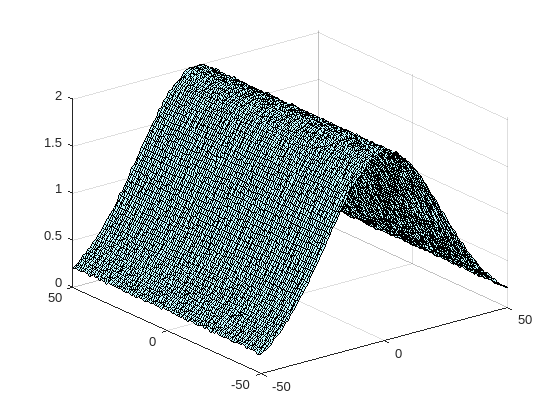

dim_bound = 100;
x_bounds = [-dim_bound*0.5:1:dim_bound*0.5] ;
y_bounds = [-dim_bound*0.5:1:dim_bound*0.5] ; 
z_surf = meshgrid(x_bounds,y_bounds) ;
z_surf = 2*exp(-0.0009*z_surf.^2) + 0.009*randn(dim_bound+1,dim_bound+1) ;

figure
surf(x_bounds,y_bounds,z_surf,"FaceColor",[195 250 255]/255 )

hold on

## Create landmarks

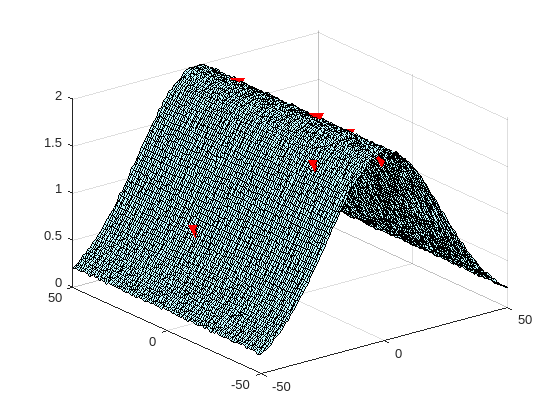

num_landmarks = 6;
coord_landmarks = zeros(3, num_landmarks);
for i = 1 : num_landmarks
    x_lm =  randi(100);
    y_lm =  randi(100) ;
    coord_landmarks(:,i) = [x_bounds(x_lm) ; y_bounds(y_lm) ; z_surf(y_lm , x_lm)];
end
coord_landmarks ;
scatter3(coord_landmarks(1,:) , coord_landmarks(2,:) , coord_landmarks(3,:) , 80 , 'red' , 'filled' , 'v' , 'MarkerEdgeColor','flat' , 'MarkerFaceColor','flat') 


clear x_lm y_lm

## Robot and sensor trajectory generation

## SLAM

% Assume that the location of the landmarks is not known a priori. This is
% coded in the form of a huge initial covariance




function [range_out] = hRadar(x_in , lm_coords)
res = x_in - lm_coords ;
range_out = sqrt(res'*res);
end